% clear work space
close all
clear var
% include working variables
load var.mat

% коэффициенты полинома линейной апроксимации
p_1 = polyfit(Dtime_2, gamma, 1);

% коэфициенты полинома нелинейной апроксимации
p_2 = polyfit(time_1, Dh_1, 2);

% сгенерируем точки, равномерно расположенные на области определения данных
xx_ex = linspace(time_1(1), time_1(end), 100);
xx_lin = linspace(Dtime_2(1) - 0.5, Dtime_2(end) + 1, 100);

% получим значения полиномов в этих точках
yy_1 = polyval(p_1, xx_lin);
yy_2 = polyval(p_2, xx_ex);

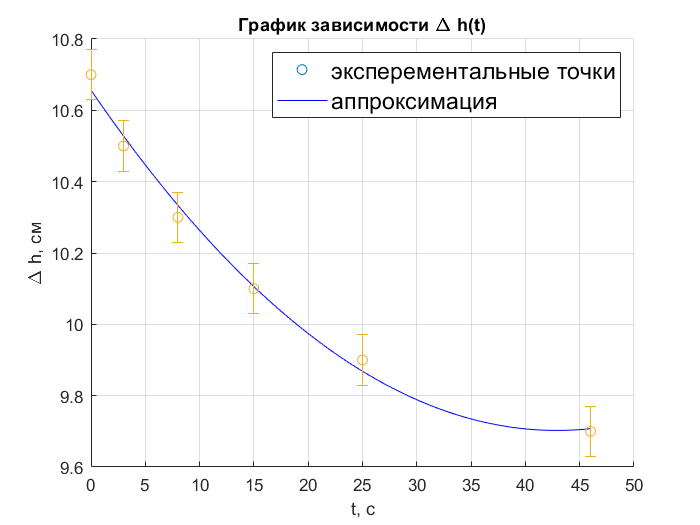

% аппроксимация нелинейного графика
fig1 = figure;

% погрешности
err = err_1;

hold on
plot(time_1, Dh_1, 'o', xx_ex, yy_2, 'b')
errorbar(time_1, Dh_1, err, 'o')

grid on
xlabel('t, с');
ylabel('\Delta h, см');
title('График зависимости \Delta h(t)');
lnd = legend('эксперементальные точки', 'аппроксимация', 'Location', 'northeast');
lnd.FontSize = 14;
hold off

set(fig1, 'Visible', 'on');

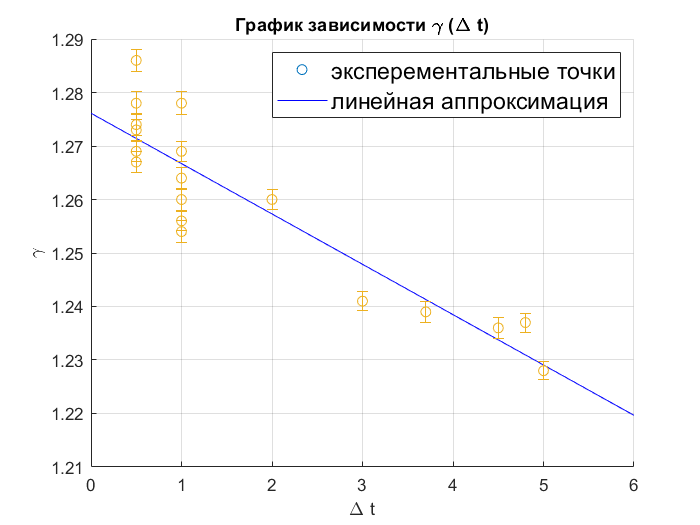

% линейное приближение МНК
fig2 = figure;

% погрешности
err = gamma_err;

hold on
plot(Dtime_2, gamma, 'o', xx_lin, yy_1, 'b')
errorbar(Dtime_2, gamma, err, 'o')

grid on
xlabel('\Delta t');
ylabel('\gamma');
title('График зависимости \gamma (\Delta t)');
lnd = legend('эксперементальные точки', 'линейная аппроксимация', 'Location', 'northeast');
lnd.FontSize = 14;
hold off

set(fig2, 'Visible', 'on');

g_1 = polyval(p_1, 0.1)

g_1 = 1.2752

g_2 = polyval(p_1, 0.2)

g_2 = 1.2742

saveas(fig1, "h(t).png");

saveas(fig2, "gamma(t).png");